# Compress Deep Learning Models, Generate Code, and Profile Performance

Note: This chapter has to be adapted to the models trained in the previous chapter. They can be found in the models directory.

This exercise requires **Deep Learning Toolbox Model Quantization Library, MATLAB Coder Interface for Deep Learning, **and **Visual Studio C++ Compiler** (check `mex -setup C++`).

Exercise 3 covers a three-part workflow to optimize deep learning models for deployment. Initially, you will apply the **projection** technique to compress a deep learning model, reducing its size while aiming to retain its accuracy. Following the compression, you will use Simulink to generate C code for both the original and compressed models. The final part involves performance profiling, where you will compare the execution time of the generated code for both models, providing insights into the efficiency improvements achieved through model compression. This exercise is designed to equip you with practical skills in model optimization, code generation, and performance analysis, essential for deploying efficient deep learning models in real-world applications.

## Load Previously Trained LSTM Network

clear
addpath(fullfile("../data"))
addpath(fullfile("../models"))
addpath(fullfile("../helpers"))

load("trained_GN.mat")
trainedGN.Layers

ans =   143×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   2-D Convolution               64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               2-D Convolution               64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      2-D Convolution           

analyzeNetwork(trainedGN)

Note that the original LSTM network has 5.9M learnables. By default, in MATLAB, DL network learnables are stored in single-precision, floating-point format (fp32). At 4 bytes (32 bits) per learnable, this translates to a total learnables size of **~23.6 MB**.

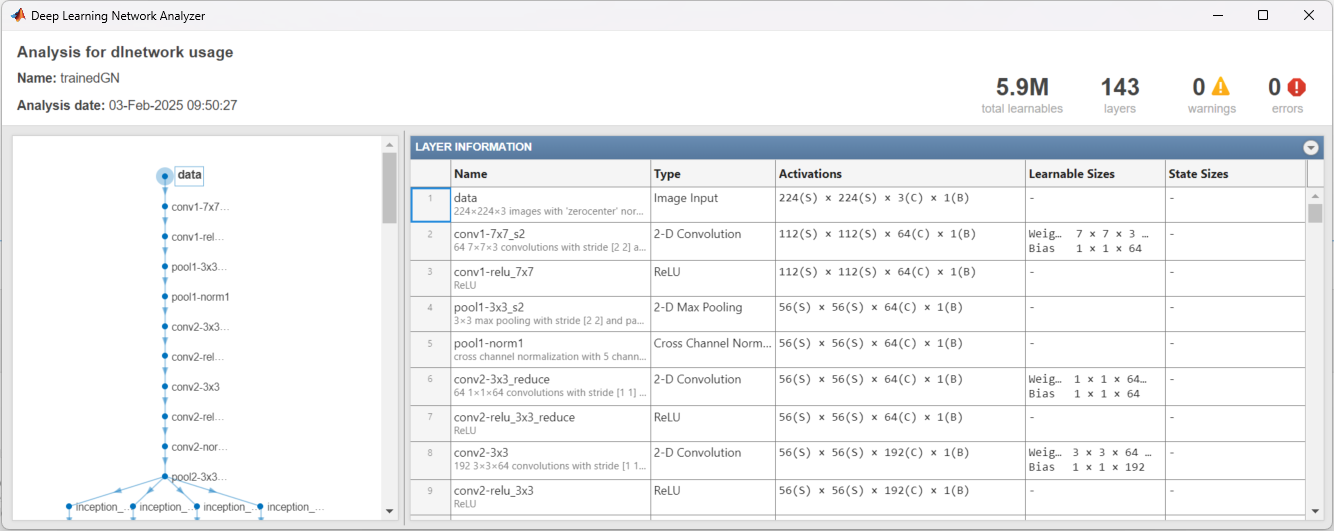

## Data Preparation

load("datastores_CNN.mat") %this file was generated in chapter 1
imgsVal_small=subset(imgsValidation,1:20:length(imgsValidation.Files));

## Model Compression - Projection

### Understanding network compression with projection

To compress a neural network, MATLAB uses a technique that involves projecting the network's layers into smaller parameter subspaces, thereby reducing the memory footprint of the model. This is done by introducing projector matrices that transform the learnable parameters into a lower-dimensional space without significantly compromising prediction accuracy. A projected deep neural network can also exhibit faster forward passes (inference) or deployed to embedded hardware using library-free C or C++ code generation, making projection a powerful technique for both reducing memory requirements and boosting throughput. To learn more about the algorithm based on principal component analysis (PCA) underlying network projection, refer to [this page](https://www.mathworks.com/company/newsletters/articles/compressing-neural-networks-using-network-projection.html).

As of R2024a, the following network layers support compression with projection:

- convolution2dLayer

- fullyConnectedLayer

- lstmLayer

- gruLayer

### Explore Compression Levels

A trade-off exists between the amount of compression we apply to the network and its accuracy. In general, reducing the number of learnable parameters in a pretrained network will reduce its accuracy. Let's experiment by compressing the network with projection by a range of increasing amounts. To do this, let's iterate over 20 values of the `ExplainedVarianceGoal` in put argument to the `compressNetworkUsingProjection `function and plot the results. Then, we can decide on a worthwhile trade-off point between network size and accuracy.

The explained variance of a network details how well the space of network activations can capture the underlying features of the data. To explore different amounts of compression, you can iterate over different values of the ExplainedVarianceGoal option of the compressNetworkUsingProjection function and compare the results.

mbSize = 48;
mbq = minibatchqueue(...
    subset(imgsTrain,1:100:length(imgsTrain.Files)),...
    MiniBatchSize=mbSize,...
    MiniBatchFormat="SSCB");

tic
npca = neuronPCA(trainedGN, mbq); % Create Neuron Principal Component Analysis (PCA) object

Using solver mode "direct".
neuronPCA analyzed 58 layers: "conv1-7x7_s2","conv2-3x3_reduce","conv2-3x3","inception_3a-1x1","inception_3a-3x3_reduce","inception_3a-3x3","inception_3a-5x5_reduce","inception_3a-5x5","inception_3a-pool_proj","inception_3b-1x1","inception_3b-3x3_reduce","inception_3b-3x3","inception_3b-5x5_reduce","inception_3b-5x5","inception_3b-pool_proj","inception_4a-1x1","inception_4a-3x3_reduce","inception_4a-3x3","inception_4a-5x5_reduce","inception_4a-5x5","inception_4a-pool_proj","inception_4b-1x1","inception_4b-3x3_reduce","inception_4b-3x3","inception_4b-5x5_reduce","inception_4b-5x5","inception_4b-pool_proj","inception_4c-1x1","inception_4c-3x3_reduce","inception_4c-3x3","inception_4c-5x5_reduce","inception_4c-5x5","inception_4c-pool_proj","inception_4d-1x1","inception_4d-3x3_reduce","inception_4d-3x3","inception_4d-5x5_reduce","inception_4d-5x5","inception_4d-pool_proj","inception_4e-1x1","inception_4e-3x3_reduce","inception_4e-3x3","inception_4e-5x5_reduce","i

toc

Elapsed time is 55.637588 seconds.


We can use this object to compress the network given a desired explained variance goal for the pca.

[dlnetProjected,info] = compressNetworkUsingProjection(trainedGN, npca, ExplainedVarianceGoal=0.9, VerbosityLevel="off");
accuracy_before_proj = testnet(trainedGN,imgsValidation,"accuracy")

accuracy_before_proj = 99.6109


accuracy_after_proj = testnet(dlnetProjected,imgsValidation,"accuracy")

accuracy_after_proj = 70.0389

Just taking a random value for the explained variance shows that we might lose to much accuracy. Let's thus optimize the accuracy with respect to the explained variance. For this we sample 20 different values using a logspace.

numValues = 20;
explainedVarGoal = 1 - logspace(-3,0,numValues);
explainedVariance = zeros(1,numValues);
learnablesReduction = zeros(1,numValues);
accuracy = zeros(1,numValues);

tic
for i = 1:numel(explainedVarGoal)
    varianceGoal = explainedVarGoal(i);

    [dlnetProjected,info] = compressNetworkUsingProjection(trainedGN, npca, ...
        ExplainedVarianceGoal=varianceGoal, ...
        VerbosityLevel="off");

    explainedVariance(i) = info.ExplainedVariance;
    learnablesReduction(i) = info.LearnablesReduction;
    
    accuracy(i) = testnet(dlnetProjected,imgsValidation,"accuracy");
end
toc %this took around 2 minutes in test runs

Elapsed time is 162.222314 seconds.


Visualize the effect of the different settings of the explained variance goal.

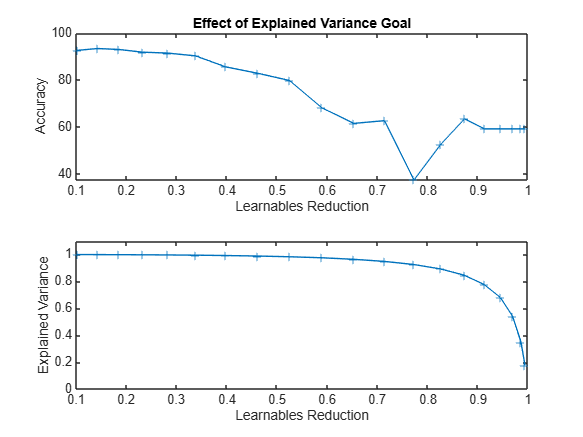

figure
tiledlayout("flow")
nexttile
plot(learnablesReduction,accuracy,'+-')
hold on
xlabel("Learnables Reduction")
ylabel("Accuracy")
title("Effect of Explained Variance Goal")

nexttile
plot(learnablesReduction,explainedVariance,'+-')
ylim([0 1.1])
ylabel("Explained Variance")
xlabel("Learnables Reduction")

The graph shows that an increase in learnable reduction has a corresponding increase in RMSE (decrease in accuracy). A learnable reduction value of around 80**%** might still yield a good network if we retrain it.

### Compress retrained googleNet via Projection of Layers

dlnetProjected = compressNetworkUsingProjection(trainedGN, npca, LearnablesReductionGoal = 0.80); % project network with 80% learnables reduction value

Compressed network has 80.0% fewer learnable parameters.
Projection compressed 58 layers: "conv1-7x7_s2","conv2-3x3_reduce","conv2-3x3","inception_3a-1x1","inception_3a-3x3_reduce","inception_3a-3x3","inception_3a-5x5_reduce","inception_3a-5x5","inception_3a-pool_proj","inception_3b-1x1","inception_3b-3x3_reduce","inception_3b-3x3","inception_3b-5x5_reduce","inception_3b-5x5","inception_3b-pool_proj","inception_4a-1x1","inception_4a-3x3_reduce","inception_4a-3x3","inception_4a-5x5_reduce","inception_4a-5x5","inception_4a-pool_proj","inception_4b-1x1","inception_4b-3x3_reduce","inception_4b-3x3","inception_4b-5x5_reduce","inception_4b-5x5","inception_4b-pool_proj","inception_4c-1x1","inception_4c-3x3_reduce","inception_4c-3x3","inception_4c-5x5_reduce","inception_4c-5x5","inception_4c-pool_proj","inception_4d-1x1","inception_4d-3x3_reduce","inception_4d-3x3","inception_4d-5x5_reduce","inception_4d-5x5","inception_4d-pool_proj","inception_4e-1x1","inception_4e-3x3_reduce","inception_4e-3

analyzeNetwork(dlnetProjected)

The new, projected network has 32.3k learnables. Still stored in fp32, their size now amounts to **~4.4 MB**.

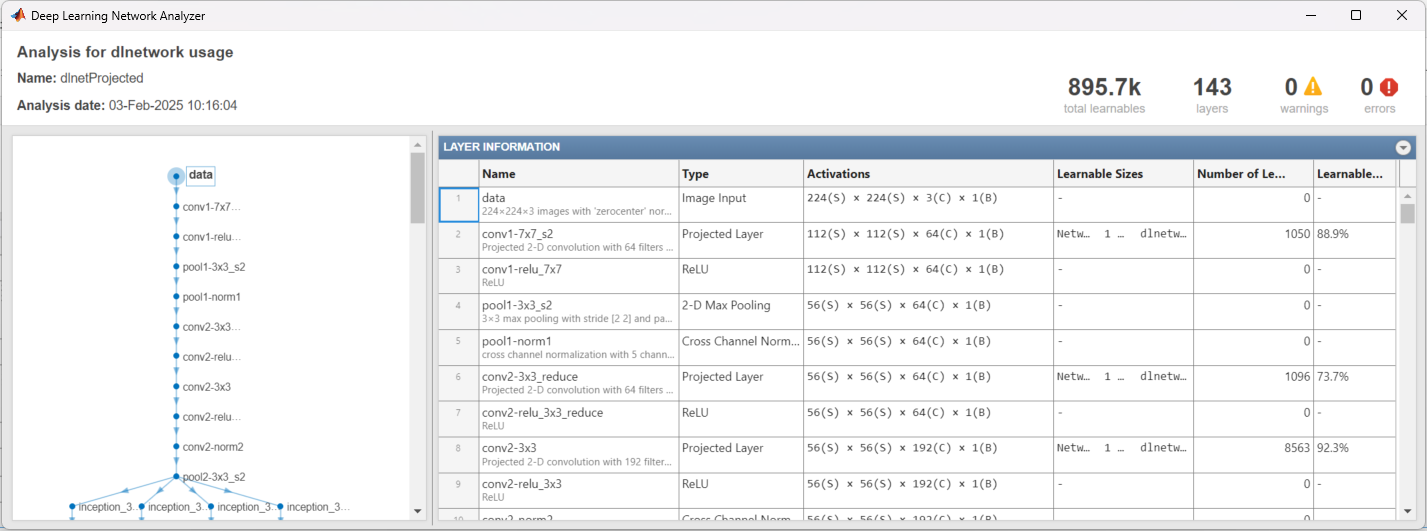

### Fine-tune the compressed CNN Network

Starting with a pretrained network, the projected network equivalent can be directly computed as demonstrated above. Although a high degree of data covariance is retained, the network may need fine-tuning as accuracy can drop following the compression. This could be a result of higher order nonlinear relations between neurons in the network needing to readjust given the linear transformation or a compounding effect if many layers are projected at once. The projected model provides a good initialization for fine-tuning by further retraining. The fine-tune retraining typically takes far fewer epochs for the accuracy to plateau and can largely recover, in many cases, the accuracy of the original network.

doTraining = true; % Set to true if you would like to run fine-tuning, otherwise, the script will load a fine-tuned model from file below

if doTraining

options = trainingOptions("sgdm", ...
    MiniBatchSize=127, ...
    MaxEpochs=30, ...
    InitialLearnRate=1e-3, ...
    ValidationData=imgsValidation, ...
    ValidationFrequency=5, ...
    Verbose=true, ...
    Plots="training-progress", ...
    Metrics="accuracy");
    
    CNNProjected = trainnet(imgsTrain,dlnetProjected,"crossentropy",options);
else
    load("projectedGN.mat");
end

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:13        0.001                            1.5483                                    41.245
            1        1       00:00:14        0.001          1.5193                                43.307                      
            5        1       00:00:23        0.001         0.68745           0.79403              73.228                 65.37
           10        2       00:00:32        0.001         0.78016           0.62953              61.417                 73.93
           15        2       00:00:38        0.001         0.56832           0.64272              77.953                73.152
           20        3       00:00:44        0.001           0.586           0.58983              76.378       

testnet(CNNProjected,imgsValidation,"accuracy")

ans = 93.7743

*Copyright 2024 The MathWorks, Inc.*